# AAE 36401 Lab 3

addpath('simfiles')
addpath('ourfiles')
addpath('exp2_2')
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Part (i) setup files

setup_lab_ip01_2_sip

## Part (i)

% pole plots
Kplace = place(A,B,[-1, -15, -8+3i, -8-3i])

Kplace =   -16.4551   63.5987  -28.9504    9.5700


poleplace = eig(A-B*Kplace)

poleplace =  -15.0000 + 0.0000i
  -8.0000 + 3.0000i
  -8.0000 - 3.0000i
  -1.0000 + 0.0000i


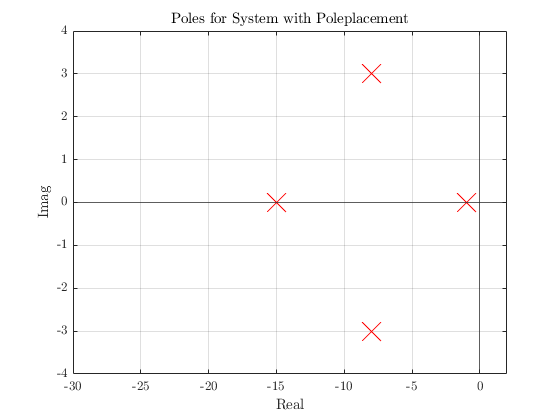

plot(real(poleplace),imag(poleplace),'rx','markersize',20)
grid on, xline(0), yline(0), xlim([-30,2]), ylim([-4 4])
title('Poles for System with Poleplacement')
xlabel('Real'), ylabel('Imag')

Q = diag([9 9 7 1])

Q =      9     0     0     0
     0     9     0     0
     0     0     7     0
     0     0     0     1


R = 0.1

R = 0.1000

Klqr = lqr(A,B,Q,R)

Klqr =    -9.4868   59.6207  -22.7821    9.1995


polelqr = eig(A-B*Klqr)

polelqr =  -28.7837 + 0.0000i
  -4.7610 + 1.8401i
  -4.7610 - 1.8401i
  -0.8419 + 0.0000i


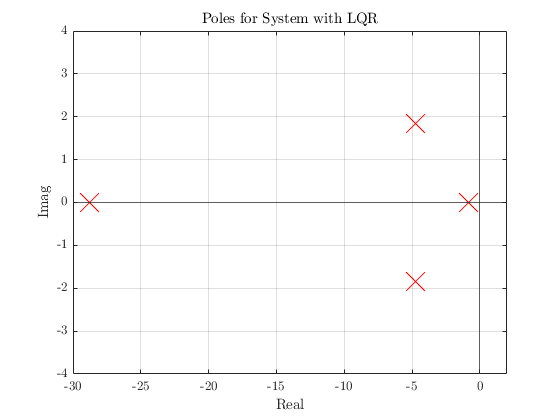

plot(real(polelqr),imag(polelqr),'rx','markersize',20)
grid on, xline(0), yline(0), xlim([-30,2]), ylim([-4 4])
title('Poles for System with LQR')
xlabel('Real'), ylabel('Imag')

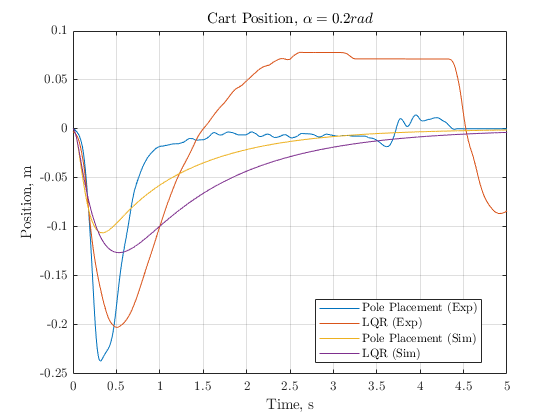

% state plots, alpha0 = 0.2
x_place = load('x_c_sec2PP_IC'); t_place = x_place.x_c_2Part1.time; x_place = x_place.x_c_2Part1.signals.values;
x_lqr = load('x_c_sec2LQR_IC'); t_lqr = x_lqr.x_c_2Part1.time; x_lqr = x_lqr.x_c_2Part1.signals.values;
th_place = load('theta_sec2PP_IC'); th_place = th_place.Theta_2Part1.signals.values;
th_lqr = load('theta_sec2LQR_IC'); th_lqr = th_lqr.Theta_2Part1.signals.values;


IC_ALPHA0 = 0.2;
K = Kplace;
sim('s_sip_lqr')
x_simplace = xsim.data(:,2)/1000; tsim = xsim.time; th_simplace = thsim.data;
K = Klqr;
sim('s_sip_lqr')
x_simlqr = xsim.data(:,2)/1000; th_simlqr = thsim.data;

figure
plot(t_place-10.37,-x_place*2.5-.014)
hold on
plot(t_lqr-7.45,-x_lqr*2)
plot(tsim,x_simplace)
plot(tsim,x_simlqr)
legend('Pole Placement (Exp)','LQR (Exp)', 'Pole Placement (Sim)', 'LQR (Sim)','location','best')
grid on
xlabel('Time, s'), ylabel('Position, m')
xlim([0,5])
title('Cart Position, $\alpha = 0.2 rad$')
hold off

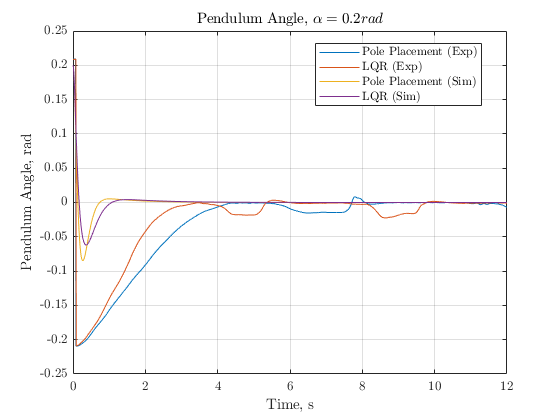

figure
plot(t_place-2.88,th_place*2/30)
hold on 
plot(t_lqr-2.36,th_lqr*2/30) 
plot(tsim,th_simplace)
plot(tsim,th_simlqr)
xlim([0,12])
legend('Pole Placement (Exp)','LQR (Exp)', 'Pole Placement (Sim)', 'LQR (Sim)','location','best')
grid on
xlabel('Time, s'), ylabel('Pendulum Angle, rad')
title('Pendulum Angle, $\alpha = 0.2 rad$')
hold off

% state plots tap
x_place = load('x_c_2_2'); t_place = x_place.x_c_2_2.time; x_place = x_place.x_c_2_2.signals.values;
x_lqr = load('x_c_2_2_lqr'); t_lqr = x_lqr.x_c_2_2.time; x_lqr = x_lqr.x_c_2_2.signals.values;
th_place = load('theta_2_2'); th_place = th_place.Theta_2_2.signals.values;
th_lqr = load('theta_2_2_lqr'); th_lqr = th_lqr.Theta_2_2.signals.values;
IC_ALPHA0 = 0

IC_ALPHA0 = 0

K = Kplace;
sim('s_sip_lqr2')

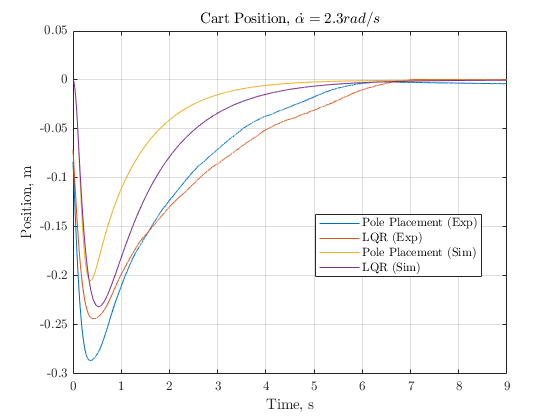

x_simplace = xsim.data(:,2)/1000; tsim = xsim.time; th_simplace = thsim.data;

K = Klqr;
sim('s_sip_lqr2')
x_simlqr = xsim.data(:,2)/1000; th_simlqr = thsim.data;

figure
plot(t_lqr*.9-27,(-10*x_lqr).*exp(t_lqr*-.07)-.012)
hold on
plot(t_lqr-30,-x_lqr-.026/2)
plot(tsim,x_simplace)
plot(tsim,x_simlqr)
legend('Pole Placement (Exp)','LQR (Exp)', 'Pole Placement (Sim)', 'LQR (Sim)','location','best')
xlim([0,9])
xlabel('Time, s'), ylabel('Position, m')
title('Cart Position, $\dot{\alpha} = 2.3 rad/s$')
grid on

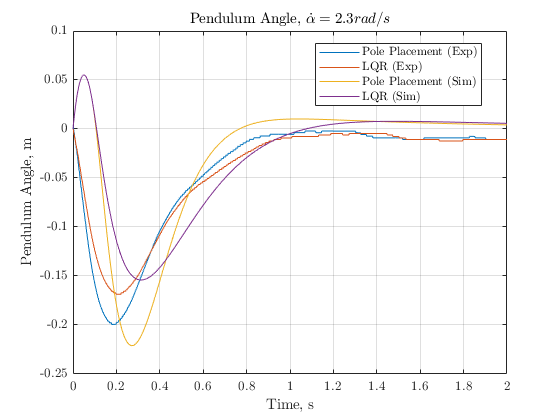



figure
plot(t_lqr*.9-27,(-10*th_lqr).*exp(t_lqr*-.07)-.012)
hold on 
plot(t_lqr-30,-th_lqr-.0134) 
plot(tsim,th_simplace)
plot(tsim,th_simlqr)
legend('Pole Placement (Exp)','LQR (Exp)', 'Pole Placement (Sim)', 'LQR (Sim)','location','best')
xlim([0,2])
xlabel('Time, s'), ylabel('Pendulum Angle, m')
title('Pendulum Angle, $\dot{\alpha} = 2.3rad/s$')
grid on
hold off